# NRG: Bulla's self-energy trick

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

In this tutorial, we will compute the impurity self-energy of the single-impurity Anderson model (SIAM) by using Bulla's self-energy trick, proposed in Bulla1998 [[R. Bulla, A. C. Hewson, and Th. Pruschke, J. Phys.: Condens. Matter **10**, 8365 (1998)](https://iopscience.iop.org/article/10.1088/0953-8984/10/37/021)].

## Exercise (a): Complete the function for the Kramers–Kronig (KK) relation

The complete correlation function, which is causal, has both real and imaginary parts. The imaginary part is given by the spectral function (up to prefactor $-\pi$) that is computed by evaluating the Lehmann representation (via `getAdisc.m`) and then by brodening the discrete spectral function (via `getAcont.m`). The real part can be computed by applying the KK relation to the imaginary part. That is, if $G (\omega) = \mathrm{Re} G(\omega) + \mathrm{i} \, \mathrm{Im} G(\omega)$, the KK relation is


$$\mathrm{Re} G (\omega) = \frac{1}{\pi} \mathrm{P} \int_{-\infty}^{+\infty} \mathrm{d}\omega' \frac{\mathrm{Im} G(\omega')}{\omega' - \omega},$$


where $\mathrm{P}$ indicates the principal value.

In the same sub-directory with this script, I provide an incomplete function, `KKi2r_Ex.m`, which is supposed to apply the KK relation for deriving the real part of a causal function from its imaginary part. Complete the parts enclosed by the comments `TODO (start)` and `TODO (end)`.

You can verify your implementation of the KK relation function, by checking whether the application of the function twice gives the original function times -1. This short script does the check with an example of the Gaussian function.

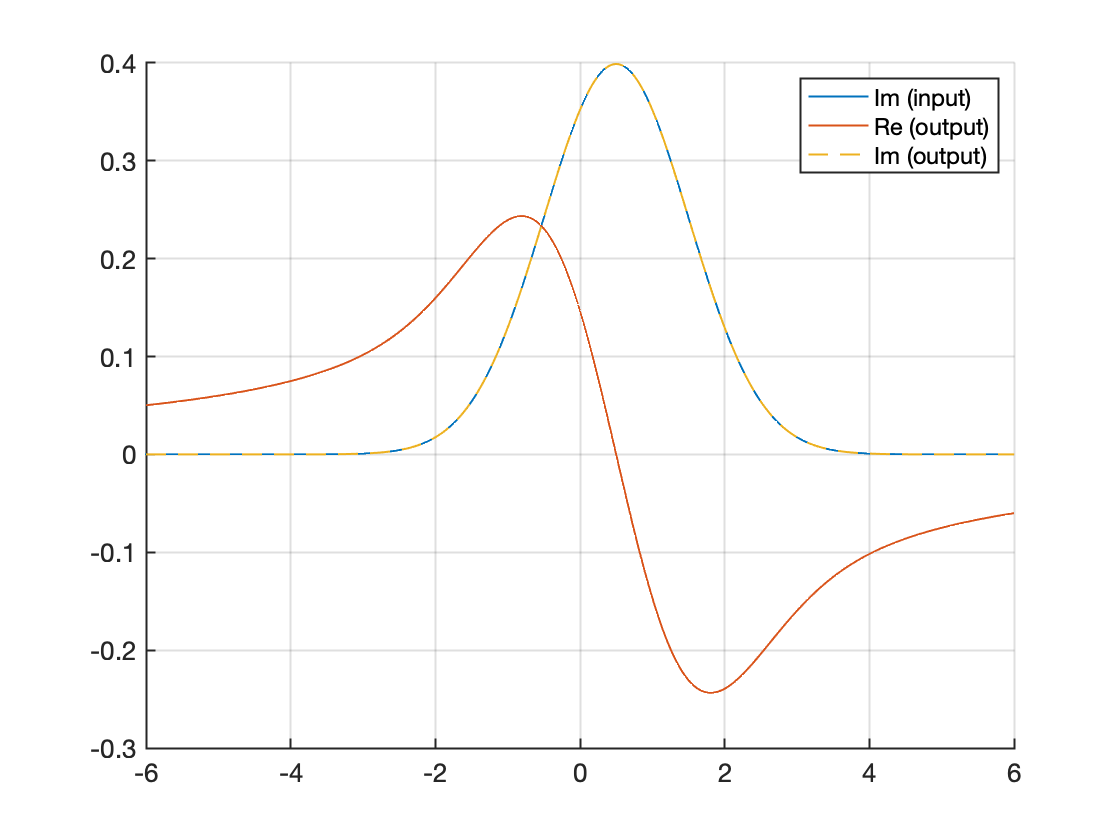

clear

ocont = getAcont(0,0,0,0); % obtain the frequency grid only
yi = exp(-0.5*((ocont - 0.5)/1).^2)/sqrt(2*pi);
yr = KKi2r(ocont,yi);
yi2 = -KKi2r(ocont,yr); % note prefactor -1

figure;
hold on;
plot(ocont,yi,'LineWidth',1);
plot(ocont,yr,'LineWidth',1);
plot(ocont,yi2,'LineWidth',1,'LineStyle','--');
hold off;
set(gca,'FontSize',13,'LineWidth',1);
legend({'Im (input)','Re (output)','Im (output)'});
grid on;
xlim([-1 1]*6);

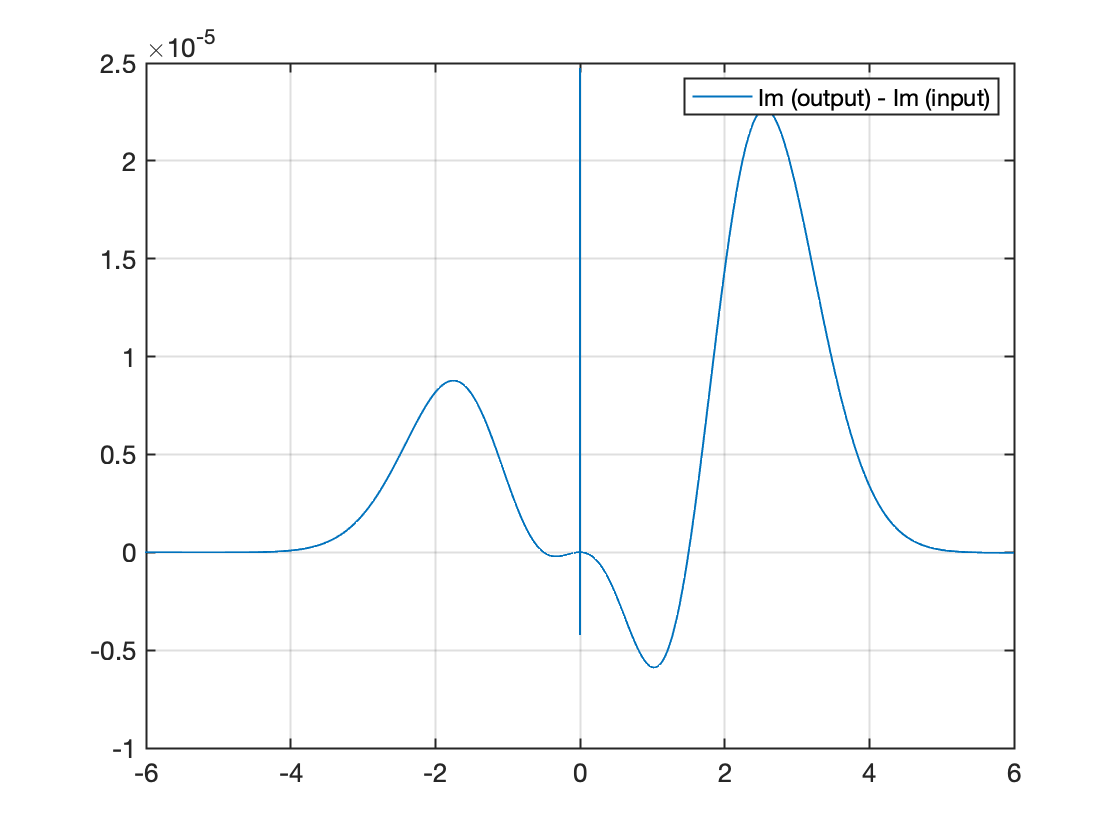

figure;
plot(ocont,yi2-yi,'LineWidth',1);
set(gca,'FontSize',13,'LineWidth',1);
legend({'Im (output) - Im (input)'});
grid on;
xlim([-1 1]*6);

This small but finite difference is due to the finite resolution and range of the frequency grid (= `ocont`).

## Exercise (b): Complete the function for Bulla's self-energy trick

With the completed `KKi2r_Ex.m`, we can now work on `SEtrick_Ex.m`, which is together in the same sub-directory with this script. Upon completion, `SEtrick_Ex.m` will compute the self-energy as the ratio of two correlation functions,


$$\Sigma (\omega) = \frac{G [ [\hat{d}_{\sigma}, \hat{H}_\mathrm{int}], \hat{d}_{\sigma}^\dagger ] (\omega)}{G [ \hat{d}_{\sigma}, \hat{d}_{\sigma}^\dagger ] (\omega)},$$


where $\hat{H}_\mathrm{int}$ is the sum of non-quadratic terms in the impurity Hamiltonian. The spectral functions of the correlation functions, namely $A [ [\hat{d}_{\sigma}, \hat{H}_\mathrm{int}], \hat{d}_{\sigma}^\dagger ] (\omega)$ and $A [ \hat{d}_{\sigma}, \hat{d}_{\sigma}^\dagger ] (\omega)$, are given as the inputs to the function. Also, if extra inputs on the impurity energy level $\epsilon_d$ and (the spectral function part of) the hybridization function $\Delta''(\omega)$ are given, then the function computes the improved estimate of the impurity spectral function by substituting the self-energy $\Sigma (\omega)$ and the complete hybridization function $\Delta (\omega)$ into $A_\mathrm{imp} = 1/(\omega - \epsilon_d - \Delta(\omega) - \Sigma(\omega))$.

Complete `SEtrick_Ex.m`, by filling out the parts enclosed by the comments `TODO (start)` and `TODO (end)`.

Let's see how Bulla's trick improves the quality of the impurity spectral function.

clear

% Hamiltonian parameters
U = 4e-3; % Coulomb interaction at the impurity
epsd = -U/2; % impurity on-site energy
Delta0 = 2.5e-4; % hybridization strength
D = 1; % half-bandwidh

ocont = getAcont(0,0,0,0);
RhoV2in = zeros(size(ocont));
RhoV2in(abs(ocont)<=D) = Delta0/pi;

Here we define `RhoV2in` ($= \Delta''(\omega)$) on the frequency grid generated by `getAcont` that is identical to the frequency grid on which the spectral functions are defined.

% NRG parameters
Lambda = 4; % discretization parameter
N = 40; % length of the Wilson chain
Nkeep = 300;

% Wilson chain
[ff,gg] = doCLD(ocont,RhoV2in,Lambda,N);

% Construct local operators
[F,Z,S,I] = getLocalSpace('FermionS');

% Particle number operators
NF = cat(3,contract(conj(F(:,:,1)),3,[1 3],F(:,:,1),3,[1 3]), ...
           contract(conj(F(:,:,2)),3,[1 3],F(:,:,2),3,[1 3]));
       
% Impurity Hamiltonian
HU = U*(NF(:,:,1)*NF(:,:,2));
H0 = HU + epsd*(NF(:,:,1)+NF(:,:,2));

% commutator [F, HU] to define the auxiliary correlator
FHU = contract(F,3,2,HU,2,1,[1 3 2]) - contract(HU,2,2,F,3,1);

% ket tensor for the impurity
A0 = getIdentity(1,2,I,2,[1 3 2]); % 1 for dummy leg

% this step does not change the data of H0, but it is concenptually
% needed; H0 is defined in the space spanned by the 2nd leg of A0
H0 = updateLeft([],[],A0,H0,2,A0);

% iterative diagonalization
Inrg = NRG_IterDiag(H0,A0,Lambda,ff,F,gg,sum(NF,3),Z,Nkeep);

22-10-28 13:12:29 | NRG: start
22-10-28 13:12:29 | #00/40 : NK=4/4, EK=0/0
22-10-28 13:12:29 | #01/40 : NK=16/16, EK=0.04838/0.04838
22-10-28 13:12:29 | #02/40 : NK=64/64, EK=3.693/3.693
22-10-28 13:12:29 | #03/40 : NK=256/256, EK=8.405/8.405
22-10-28 13:12:29 | #04/40 : NK=304/1024, EK=6.784/20.2
22-10-28 13:12:29 | #05/40 : NK=320/1216, EK=8.548/14.89
22-10-28 13:12:29 | #06/40 : NK=304/1280, EK=6.653/20.33
22-10-28 13:12:30 | #07/40 : NK=320/1216, EK=8.38/14.7
22-10-28 13:12:30 | #08/40 : NK=304/1280, EK=6.87/19.83
22-10-28 13:12:30 | #09/40 : NK=320/1216, EK=8.87/15.18
22-10-28 13:12:30 | #10/40 : NK=304/1280, EK=7.641/20.69
22-10-28 13:12:30 | #11/40 : NK=312/1216, EK=9.799/16.75
22-10-28 13:12:31 | #12/40 : NK=314/1248, EK=9.224/22.47
22-10-28 13:12:31 | #13/40 : NK=319/1256, EK=10.59/20.02
22-10-28 13:12:31 | #14/40 : NK=326/1276, EK=10.57/23.43
22-10-28 13:12:32 | #15/40 : NK=320/1304, EK=10.99/22.73
22-10-28 13:12:32 | #16/40 : NK=326/1280, EK=10.73/24.62
22-10-28 13:12:32 | #


TK = 0.4107*sqrt(U*Delta0/2)*exp(-pi*U/8/Delta0 + pi*Delta0/2/U);

T = 1e-10;
Inrg = getRhoFDM(Inrg,T);

22-10-28 13:12:38 | Construct full density matrix @ T = 1e-10.
22-10-28 13:12:39 | WRN: sum(Inrg.RD{end}) > 1e-2 ; chain length may not be long enough.
Elapsed time: 1.087s, CPU time: 7.47s, Avg # of cores: 6.874



[odisc,Adisc1] = getAdisc(Inrg,F(:,:,1),F(:,:,1),Z);

22-10-28 13:12:39 | Correlation function for anti-commuting operators.
22-10-28 13:12:39 | #00/40 : sum(Adisc) = 0
22-10-28 13:12:39 | #01/40 : sum(Adisc) = 0
22-10-28 13:12:39 | #02/40 : sum(Adisc) = 0
22-10-28 13:12:39 | #03/40 : sum(Adisc) = 0
22-10-28 13:12:39 | #04/40 : sum(Adisc) = 4.809e-08
22-10-28 13:12:39 | #05/40 : sum(Adisc) = 4.087e-06
22-10-28 13:12:39 | #06/40 : sum(Adisc) = 0.0004103
22-10-28 13:12:39 | #07/40 : sum(Adisc) = 0.0004265
22-10-28 13:12:40 | #08/40 : sum(Adisc) = 0.002042
22-10-28 13:12:40 | #09/40 : sum(Adisc) = 0.002106
22-10-28 13:12:40 | #10/40 : sum(Adisc) = 0.008652
22-10-28 13:12:40 | #11/40 : sum(Adisc) = 0.009074
22-10-28 13:12:40 | #12/40 : sum(Adisc) = 0.04177
22-10-28 13:12:40 | #13/40 : sum(Adisc) = 0.2318
22-10-28 13:12:41 | #14/40 : sum(Adisc) = 0.8364
22-10-28 13:12:41 | #15/40 : sum(Adisc) = 0.8471
22-10-28 13:12:41 | #16/40 : sum(Adisc) = 0.9346
22-10-28 13:12:41 | #17/40 : sum(Adisc) = 0.9379
22-10-28 13:12:41 | #18/40 : sum(Adisc) = 0.96

[~    ,Adisc2] = getAdisc(Inrg,FHU(:,:,1),F(:,:,1),Z);

22-10-28 13:12:45 | Correlation function for anti-commuting operators.
22-10-28 13:12:45 | #00/40 : sum(Adisc) = 0
22-10-28 13:12:45 | #01/40 : sum(Adisc) = 0
22-10-28 13:12:45 | #02/40 : sum(Adisc) = 0
22-10-28 13:12:45 | #03/40 : sum(Adisc) = 0
22-10-28 13:12:45 | #04/40 : sum(Adisc) = 9.619e-11
22-10-28 13:12:46 | #05/40 : sum(Adisc) = 8.174e-09
22-10-28 13:12:46 | #06/40 : sum(Adisc) = 8.206e-07
22-10-28 13:12:46 | #07/40 : sum(Adisc) = 8.53e-07
22-10-28 13:12:46 | #08/40 : sum(Adisc) = 4.085e-06
22-10-28 13:12:46 | #09/40 : sum(Adisc) = 4.213e-06
22-10-28 13:12:47 | #10/40 : sum(Adisc) = 1.73e-05
22-10-28 13:12:47 | #11/40 : sum(Adisc) = 1.815e-05
22-10-28 13:12:47 | #12/40 : sum(Adisc) = 8.353e-05
22-10-28 13:12:47 | #13/40 : sum(Adisc) = 0.0004637
22-10-28 13:12:47 | #14/40 : sum(Adisc) = 0.001673
22-10-28 13:12:47 | #15/40 : sum(Adisc) = 0.001694
22-10-28 13:12:48 | #16/40 : sum(Adisc) = 0.001869
22-10-28 13:12:48 | #17/40 : sum(Adisc) = 0.001876
22-10-28 13:12:48 | #18/40 : su


[~    ,Acont1] = getAcont(odisc,Adisc1,log(Lambda),T/5);
[~    ,Acont2] = getAcont(odisc,Adisc2,log(Lambda),T/5);

Before running the self-energy trick function, we plot how the two spectral functions `Acont1` and `Acont2` look like.

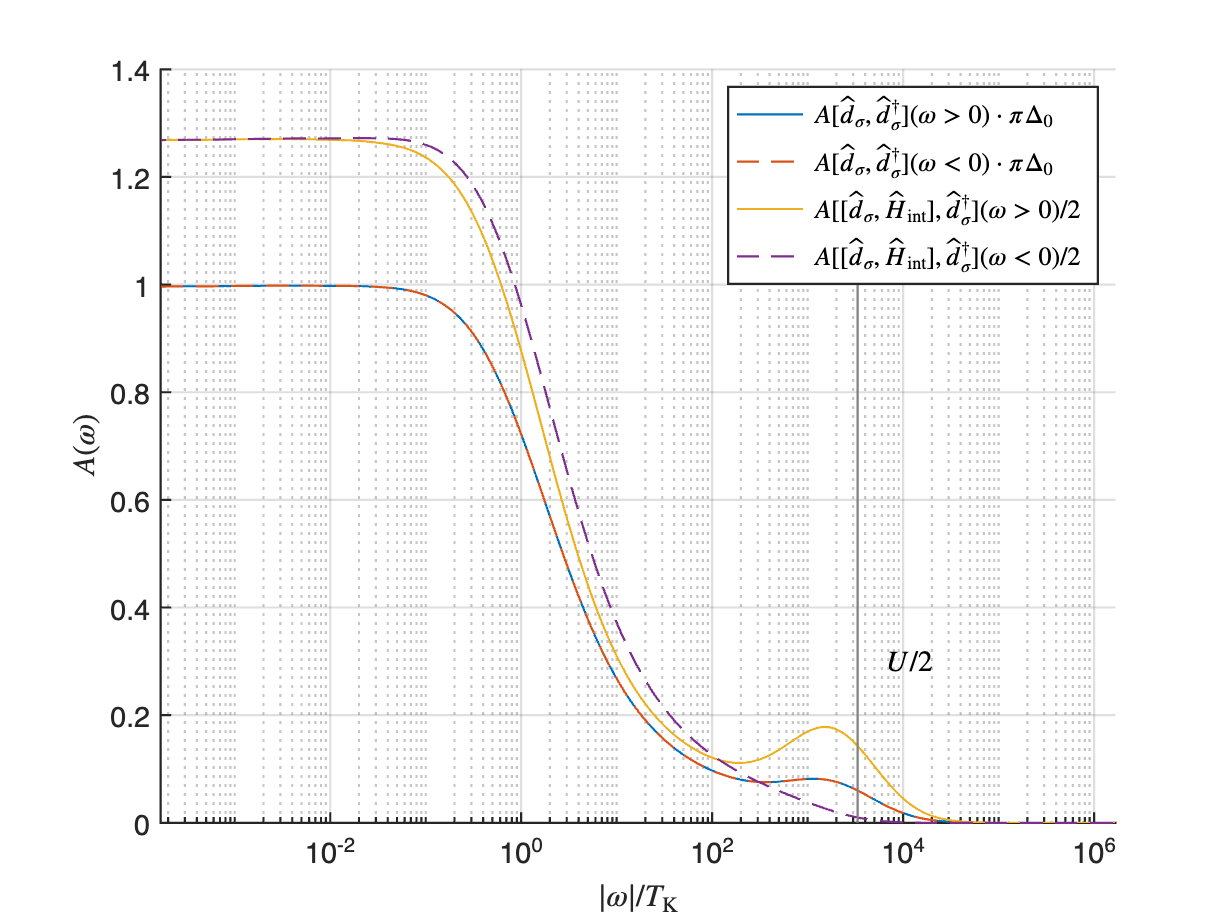

figure;
hold on;
plot(ocont(ocont>0)/TK,Acont1(ocont>0)*(pi*Delta0), ...
    'LineWidth',1,'LineStyle','-');
plot(-ocont(ocont<0)/TK,Acont1(ocont<0)*(pi*Delta0), ...
    'LineWidth',1,'LineStyle','--');
plot(ocont(ocont>0)/TK,Acont2(ocont>0)/2, ...
    'LineWidth',1,'LineStyle','-');
plot(-ocont(ocont<0)/TK,Acont2(ocont<0)/2, ...
    'LineWidth',1,'LineStyle','--');
% guide to the eye
plot(U/2/TK*[1 1],[0 1],'LineWidth',1,'LineStyle','-', ...
    'Color',[1 1 1]*0.5);
text(U/TK,0.3,'$U/2$','FontSize',13, ...
    'Interpreter','latex','HorizontalAlignment','left');
hold off;
set(gca,'FontSize',13,'LineWidth',1,'XScale','log');
legend({['$A[\hat{d}_{\sigma}, \hat{d}_{\sigma}^\dagger](\omega > 0) ' ...
    '\cdot \pi \Delta_0$'], ...
    ['$A[\hat{d}_{\sigma}, \hat{d}_{\sigma}^\dagger](\omega < 0) ' ...
    '\cdot \pi \Delta_0$'], ...
    ['$A[[\hat{d}_{\sigma}, \hat{H}_\mathrm{int}], ' ...
    '\hat{d}_{\sigma}^\dagger](\omega > 0) /2$'], ...
    ['$A[[\hat{d}_{\sigma}, \hat{H}_\mathrm{int}], ' ...
    '\hat{d}_{\sigma}^\dagger](\omega < 0) /2$']}, ...
    'Interpreter','latex');
xlabel('$|\omega|/T_\mathrm{K}$','Interpreter','latex');
ylabel('$A (\omega)$', ...
    'Interpreter','latex');
grid on;
xlim([T 1]/TK);

The bare spectral function is symmetric, i.e., $A[\hat{d}_{\sigma}, \hat{d}_{\sigma}^\dagger](\omega) = A[\hat{d}_{\sigma}, \hat{d}_{\sigma}^\dagger](-\omega)$, but the auxiliary spectral function $A[[\hat{d}_{\sigma}, \hat{H}_\mathrm{int}], \hat{d}_{\sigma}^\dagger](\omega)$ is not. This broken symmetry in the latter is clear, since $\hat{H}_\mathrm{int}$ does not respect the particle-hole symmetry.

Now let's perform the self-energy trick.

[SE,Aimp] = SEtrick_Ex (ocont,Acont1,Acont2,epsd,RhoV2in);

How much does this trick improve the quality of the spectral function?

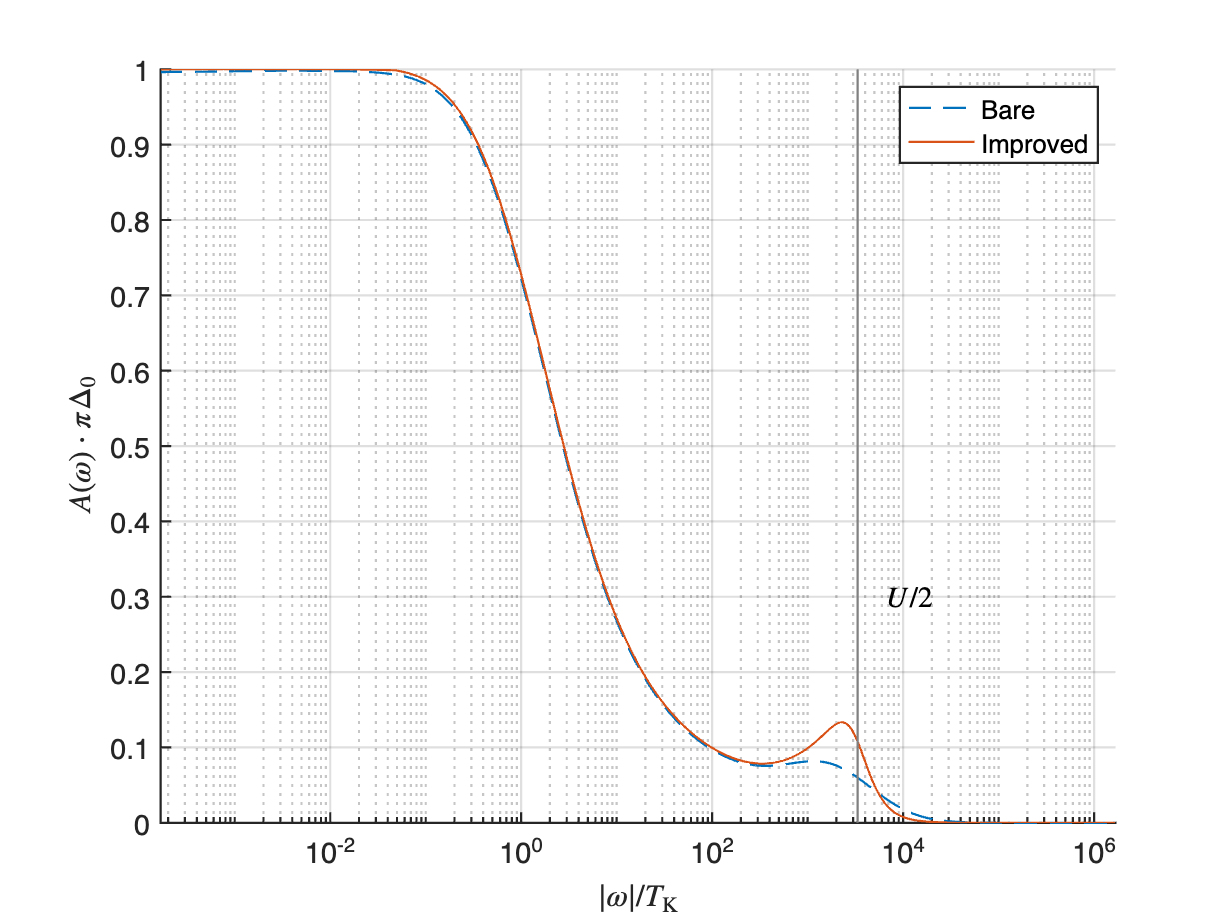

figure;
hold on;
plot(ocont(ocont>0)/TK,Acont1(ocont>0)*(pi*Delta0), ...
    'LineWidth',1,'LineStyle','--');
plot(ocont(ocont>0)/TK,Aimp(ocont>0)*(pi*Delta0), ...
    'LineWidth',1,'LineStyle','-');
% guide to the eye
plot(U/2/TK*[1 1],[0 1],'LineWidth',1,'LineStyle','-', ...
    'Color',[1 1 1]*0.5);
text(U/TK,0.3,'$U/2$','FontSize',13, ...
    'Interpreter','latex','HorizontalAlignment','left');
hold off;
set(gca,'FontSize',13,'LineWidth',1,'XScale','log');
legend({'Bare','Improved'});
xlabel('$|\omega|/T_\mathrm{K}$','Interpreter','latex');
ylabel('$A (\omega) \cdot \pi \Delta_0$', ...
    'Interpreter','latex');
grid on;
xlim([T 1]/TK);

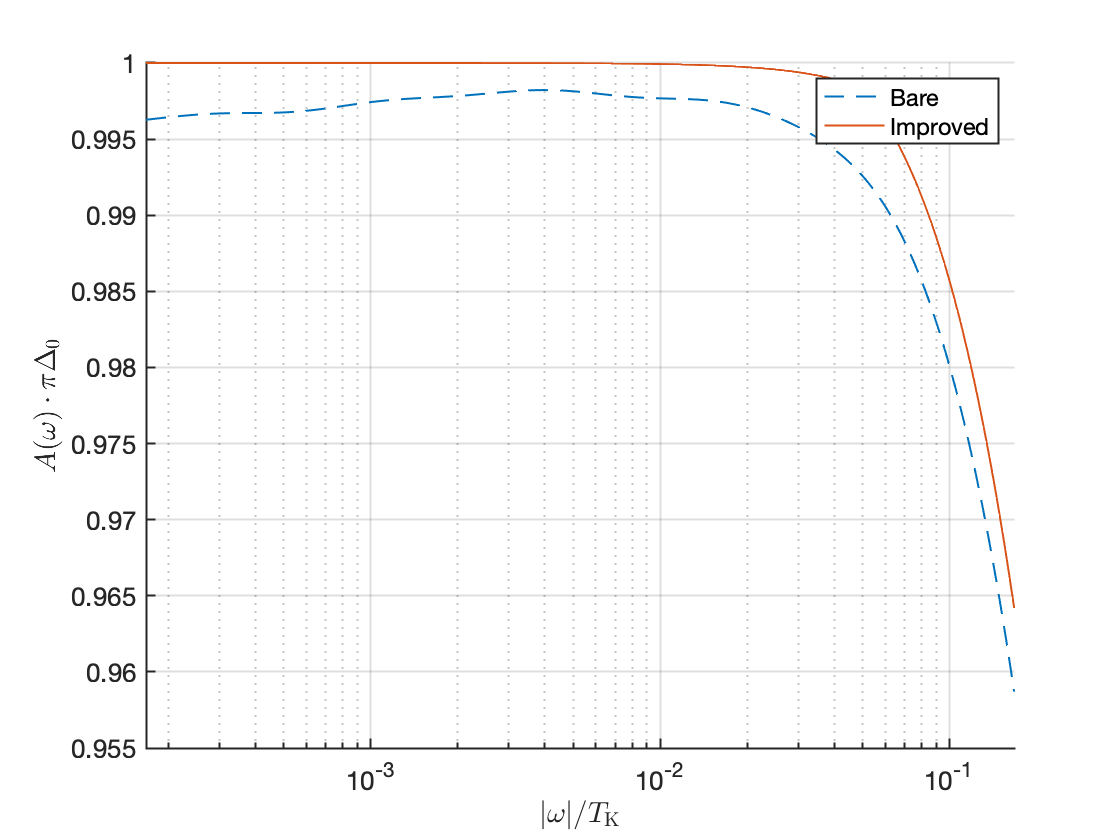

% zoom-in onto low frequencies
figure;
hold on;
plot(ocont(ocont>0)/TK,Acont1(ocont>0)*(pi*Delta0), ...
    'LineWidth',1,'LineStyle','--');
plot(ocont(ocont>0)/TK,Aimp(ocont>0)*(pi*Delta0), ...
    'LineWidth',1,'LineStyle','-');
hold off;
set(gca,'FontSize',13,'LineWidth',1,'XScale','log');
legend({'Bare','Improved'});
xlabel('$|\omega|/T_\mathrm{K}$','Interpreter','latex');
ylabel('$A (\omega) \cdot \pi \Delta_0$', ...
    'Interpreter','latex');
grid on;
xlim([1 1e3]*T/TK);

We see two clear improvements in the new curve.

- The side peaks centered around $\omega = \pm U/2$ are better resolved in `Aimp`. In the original `Acont1`, those peaks were over-broadened because of the nature of the logarithmic broadening; the spectral features at higher frequencies are broadened with larger widths proportional to their positions. Such logarithmic choice of the broadening widths is inevitable to recover the continuity, since NRG calculations start with the logarithmic discretization of the bath. This over-broadening is a well-known shortcoming of the NRG method. One can use $z$ averaging and the adaptive broadening to remedy the problem; see Lee2016 [[S.-S. B. Lee and A. Weichselbaum, Phys. Rev. B **94**, 235127 (2016)](https://journals.aps.org/prb/abstract/10.1103/PhysRevB.94.235127)] for details.

- In the original `Acont1`, the shape of the Kondo peak centered at the Fermi level ($\omega = 0$) has wriggles. On the other hand, `Aimp` reveals much smoother lineshape of the Kondo peak.